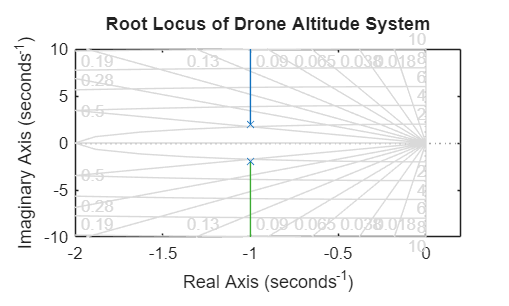

clc;
clear;
close all;

s = tf('s');

% Drone plant
G = 1/(s^2 + 2*s + 5);

% Root locus plot
figure;
rlocus(G);
grid on;
title('Root Locus of Drone Altitude System');


% Open-loop poles
p_open = pole(G)

p_open =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i



% Stability of open-loop plant
if all(real(p_open) < 0)
    disp('Open-loop plant is STABLE');
elseif any(real(p_open) > 0)
    disp('Open-loop plant is UNSTABLE');
else
    disp('Open-loop plant is MARGINALLY STABLE');
end

Open-loop plant is STABLE



% Check closed-loop stability for different K values
K_values = [5 20 60];

for i = 1:length(K_values)
    K = K_values(i);
    T = feedback(K*G, 1);
    p_closed = pole(T);
    
    fprintf('\nFor K = %d:\n', K);
    disp(p_closed);
    
    if all(real(p_closed) < 0)
        disp('Closed-loop system is STABLE');
    elseif any(real(p_closed) > 0)
        disp('Closed-loop system is UNSTABLE');
    else
        disp('Closed-loop system is MARGINALLY STABLE');
    end
end


For K = 5:


  -1.0000 + 3.0000i
  -1.0000 - 3.0000i



Closed-loop system is STABLE



For K = 20:


  -1.0000 + 4.8990i
  -1.0000 - 4.8990i



Closed-loop system is STABLE



For K = 60:


  -1.0000 + 8.0000i
  -1.0000 - 8.0000i



Closed-loop system is STABLE
